x = importdata('jearcabo_ecg')

x =     0.5000    0.1545   -0.4045   -0.4045    0.1545    0.5000    0.1545   -0.4045   -0.4045    0.1545    0.5000    0.1545   -0.4045   -0.4045    0.1545    0.5000    0.1545   -0.4045   -0.4045    0.1545    0.5000    0.1545   -0.4045   -0.4045    0.1545    0.5001    0.1551   -0.4024   -0.3988    0.1669    0.5232    0.1930   -0.3466   -0.3241    0.2595    0.6306    0.3111   -0.2218   -0.1957    0.3894    0.7610    0.4416   -0.0914   -0.0655    0.5186    0.8872    0.5606    0.0142    0.0187    0.5733


fs = 300;
Ts = 1/fs;

t = [0:length(x)-1]*Ts;
title('Señal ECG contaminada')
ylabel('magnitud')
xlabel('Tiempo [s]')
grid on 
grid minor 


subplot(211),plot(t, x)

X = fft(x,fs);
Xv = fftshift(X);
f = (-fs/2:fs/2-1)/(fs/2);


Aprender a hacer un filtro digital 


yl = ylim;
hold on

xlabel('\omega/\pi')
ylabel('Magnitude')
grid

fc = 0.15;
fn = [0 fc fc 1];
mn = [1 1 0 0];
[b,a] = yulewalk(14,fn,mn);
[h,w] = freqz(b,a,128); %respuesta en frecuencia de un filtro 


Aplicar el filtro 

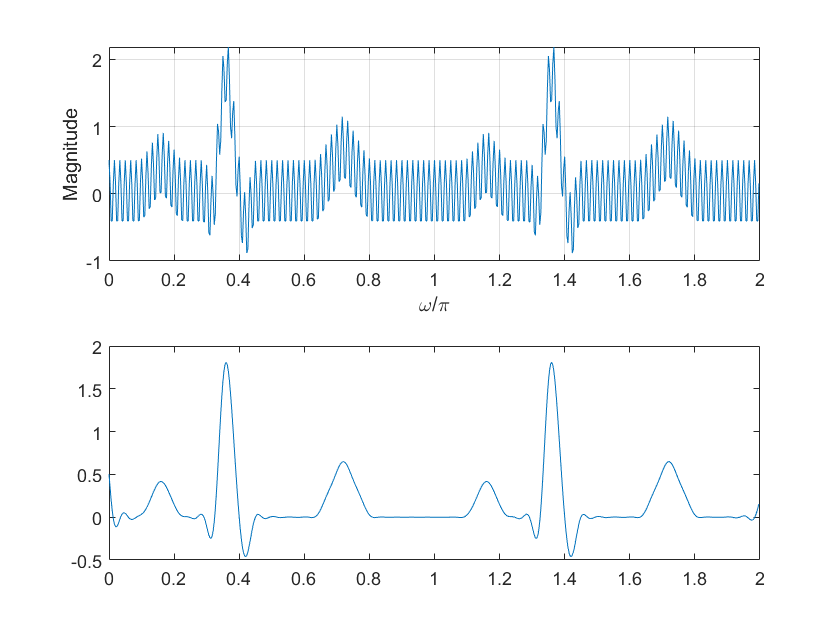

figure(1)
x_f = filtfilt(b,a,x);
subplot(212),plot(t, x_f)

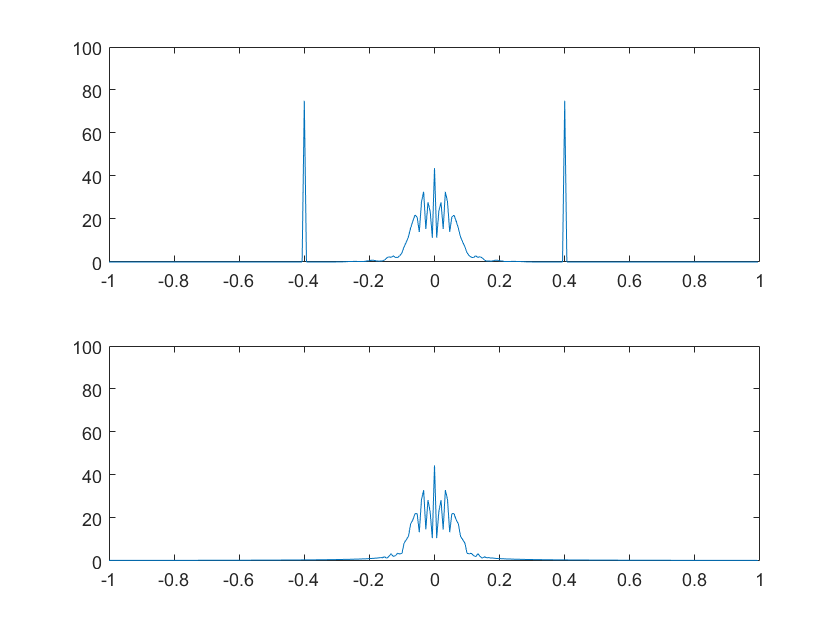



X_f = fft(x_f,fs);
Xv_f = fftshift(X_f);
figure(2)
subplot(211),plot(f,abs(Xv))
axis([-1 1 0 100])
subplot(212),plot(f,abs(Xv_f))
axis([-1 1 0 100])

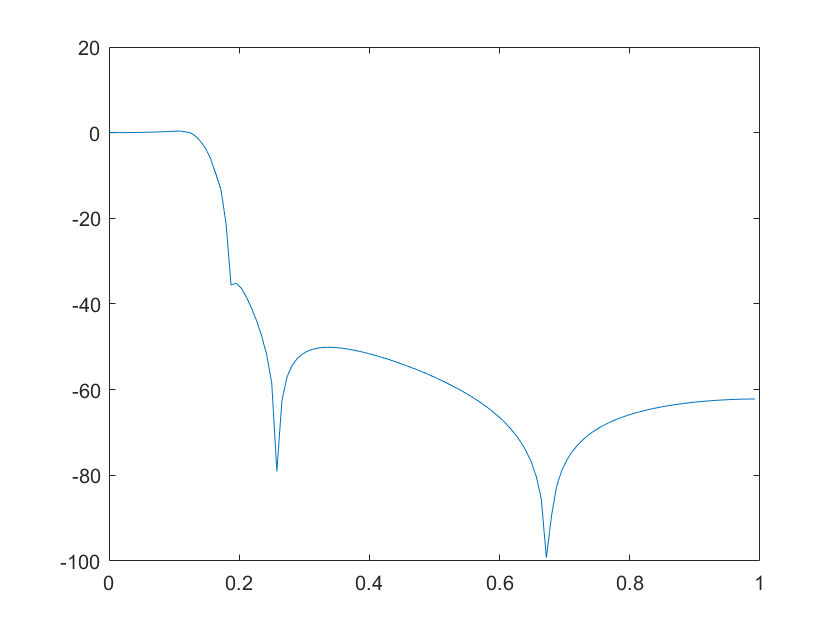



figure(3)
plot(w/pi,mag2db(abs(h)))

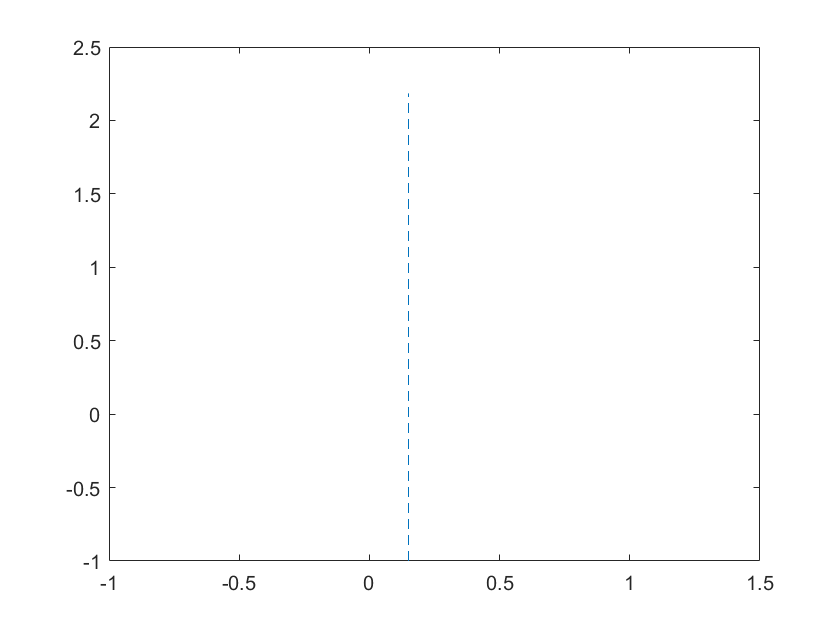

figure(4)
plot(fn(2:3),yl,'--')